# 04 Spektrogram

Nejzákladnější a nejužívanější technikou zpracování signálů je spektrální analýza dominantních harmonických složek zkoumaného signálu a sledování jejich změny v čase. Ve vztahu k definici Diskrétní Fourierovy Transformace (DFT) je teoretickým požadavkem periodický signál, přičemž jeho spektrum je spočteno právě pro jednu periodu. Při analýze neperiodických signálů se tváříme, že jednu periodu je celý signál délky $N$ – **periodizace**.


$$\textrm{DFT}:Y\left\lbrack f_k \right\rbrack =\frac{1}{N}\sum_{n=0}^{N-1} y\left\lbrack n\right\rbrack {\cdot e}^{-\textrm{ik2}\pi \frac{N}{f_s }} ;{\;f}_k =k\cdot \frac{f_s }{N};y\left\lbrack 0\right\rbrack \ldotp \ldotp \ldotp \textrm{první}\;\textrm{vzorek}$$


V případě, že umělá perioda není celým násobkem periody jednotlivých harmonických složek signálu (tj. vždy u signálů z praxe), dochází mezi napojením period signálu k nespojitostem a vzniku skoků v amplitudě. Do zperiodizovaného signálu je tak přidána další komponenta, která se ve spektru projeví rozmazáním spektrálních čar – **prosakováním**.

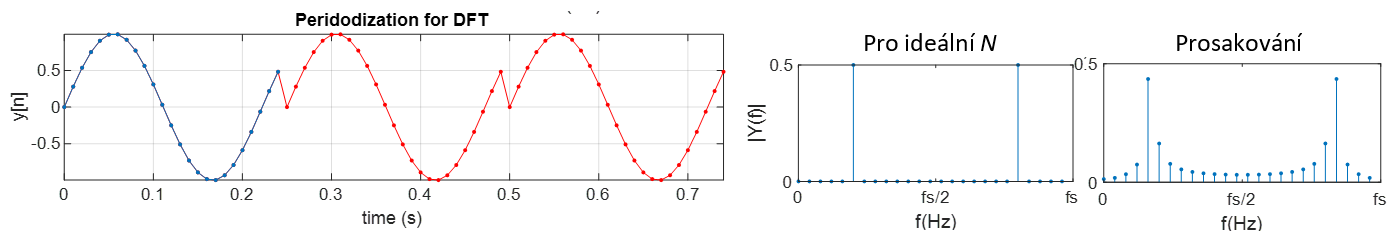

Prosakování lze výrazně eliminovat přenásobením původního signálu **váhovacím oknem**, která na okrajích signál tlumí a střední část nemění. Při periodizaci tak dojde k utlumení nespojitostí, nicméně signál je částečně zdeformován - amplitudově modulován. Dochází tak k mísení dvou signálů (podobně jako u hetorodynního směšování -  amplitudové modulace. Násobení harmonických signálů $y_1 \left(t\right)\cdot y_2 \left(t\right)$ o frekvenci $f_1$ a $f_2$ se ve spektru projeví spektrálními čarami $f_1 \pm f_2$. U násobení složitějších signálů pak vznikají všechny kombinace spektrálních čar $f_{1k}$ s $f_{2k}$. U váhování oknem se jedná o všechny složky signálu a spektrálních čár okna, které jsou postupně míseny navzájem. To vede sice k potlačení prosakování, ovšem za cenu rozmazání spektra při heterodynním směšování. Váhováním se také snižuje energie signálu na okrajích, proto bez kompenzace dochází k narušení Parsevalovi rovnosti. Existuje mnoho typů oken (Hamming, Hann, Blackman aj.), jejichž vlastnosti se mění v závislosti na potlačení prosakování za cenu většího mísení (spektrum okna).

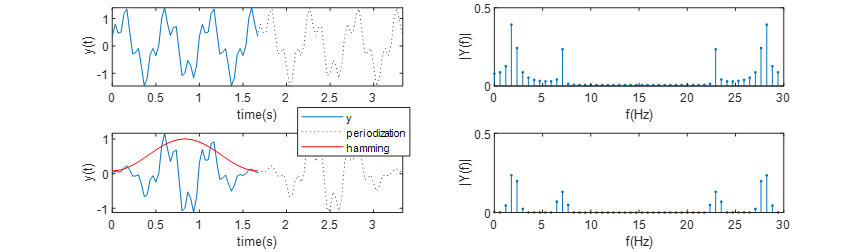

Zahušťení spektra

Originální signál, ale i signál váhovaný oknem, lze prodloužit doplněním nulami na konec signálu. Ačkoli doplnění nulami nepřidá k signálu žádnou informaci (energii), dojde při výpočtu DFT k **zahuštění spektra**, protože počet vzorků signálu se rovná počtu spektrálních čar $N=K$. Toho se využívá v případech, kdy potřebujeme i z krátkého signálu vytvořit husté spektrum. S výhodou se uplatňuje pro algoritmus FFT, který pracuje efektivně při délce signálu přesně s $2^n$** vzorků**.

Časová segmentace

V reálných aplikacích se setkáváme z nestacionárními signály (měnící parametry v čase), u nichž výpočet spektra z celého signálu neumožňuje analýzu vývoje frekvenčních parametrů a sledování dynmických změn. Spektrum signálu ale lze popsat jen pro výsek signálu (segment), vybraný časový interval $t_{w\;}$– **časové okno (time window)**. Postupným posouváním segmentačního okna a výpočtem spektra získáme jeho časový vývoj, tzv. **spektrogram**. Velikost okna závisí na kompromisu časového a frekvenčního rozlišení (přepokládaná doba stacionarity). Nesmíme ale zapomínat, že počet spektrálních čar je vždy roven počtu vzorků v signálu $K=N$. Spektrální čáry jsou vždy rovnoměrně rozloženy do intervalu spektra $\left.f_k \in <0,f_s \right)$, tedy rozestup mezi spektrálními čarami je $\Delta f=\frac{f_s }{K}$. Pro segmentaci s krátkým oknem (malé $\Delta t$ - **velké časové** rozlišení) pracujeme s malým počtem vzorků, proto spektrum má **malé frekvenční** rozlišení (velké $\Delta f$). Pro popis rychlých časových změn signálu musíme signál analyzovat po krátkých úsecích, naopak pro přesné stanovení frekvence potřebujeme dlouhý stacionární úsek signálu. Protože většina biologických signálů mění svoje vlastnosti v čase, musíme vždy správně volit kompromis mezi časovým a frekvenčním rozlišením, tj. zvolit optimální délku okna. 

Abychom zvýšili časové rozlišení analýzy, nemusíme signál  rozdělovat rovnoměrně (stříhání pásky), ale můžeme pracovat s částečně se překrývajícími **segmenty** (vykopíruji úsek, další bude jen částečně posunutý). Segmenty signálu mohou na sebe navazovat (segmentace bez překryvu - stříhání pásky), nebo se navzájem překrývat (segmentace s překryvem). Největší možný překryv je logicky $N-1$, tj. posun okna po vzorku. Kvůli poměru výpočetní náročnosti v závislosti na počtu oken proto volíme překryv (**negative overlap**) nejčastěji mezi 50‑90 % okna (del zvoleného váhovacího okna omezující prosakovaní). 

**Spektrogram** je dvojrozměrná matice spektrálních čar $Y\left(f_k ,t_w \right)$, proto je výhodné hodnoty modulu zobrazovat barevnou škálou jako obrázek. Pro zvětšení dynamického rozsahu amplitudy se používá výkonová spektrální hustota (**PSD**) $|Y\left(f_k ,t_w \right)|^2$ v dB.

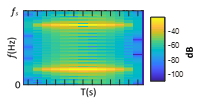Př.: Spektrum finitního harmonického signálu. Spektrum se zrcadlí kolem $\frac{f_s }{2}$.

Odhad PSD je způsob, jakým ze signálu získáme informaci o stacionární frekvenční složce a potlačíme stochastické komponenty. Měnící se složka bude v jednotlivých segmentech spektrogramu různá, naopak stacionární společná pro všechny. Průměrem spektrogramu přes čas (NE v dB!) získáme **odhad PSD**, který lze také přepočítat do dB. 


$$\begin{array}{l}
\bar{Y_{\textrm{PSD}} } \left(f_k \right)=\frac{1}{W}\sum_w |Y\left(f_k ,t_w \right)|^2 ;\;\;\;W\;\ldotp \ldotp \ldotp \textrm{počet}\;\textrm{segmentačních}\;\textrm{oken}\\
\bar{Y_{\textrm{PSD}} } \left(f_k \right)\;\left\lbrack \textrm{dB}\right\rbrack =10\;\log_{10} \left(\bar{Y_{\textrm{PSD}} } \left(f_k \right)\;\right)\\

\end{array}$$


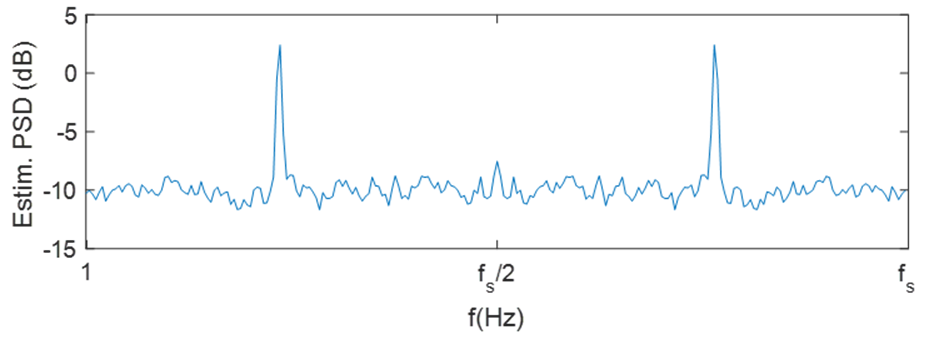Př.: Odhad PSD, peaky odpovídají stacionární složce signálu. Spektrum se zrcadlí kolem $\frac{f_s }{2}$.

**Cíle:**

    **1) Prosakování ve spektru:**

- Generujte signál se dvěma harmonickými složkami

- Délku signálu volte jako celočíselný násobek harmonických složek, vykreslete spektrum

- Ořízněte signál na ***neceločíselný*** násobek, vykreslete spektrum - prosakování

- Váhujte signál oknem (např. Hamming), vykreslete spektrum 

- Doplňte signál nulami, vykreslete spektrum

    **2) Implementujte algoritmus výpočtu spektrogramu**

- Časová segmentace s překryvem

- Váhování oknem

- Doplnění segmentu nulami

- Výpočet spektra

- Výpočet výkonového spektra PSD

- Zapouzdřete do funkce `my_spectrogram.m`

    **3) Vypočítejte a zobrazte spektrogram s vhodným nastavením pro:**

- Chirp signál s 50 Hz rušením

- Harmonický zázněj v šumu

- Aliasing - chirp signál

**Užitečné funkce: **

## `Nápověda:`

### 1) Periodizace signálu, prosakování, váhování a zahuštění spektra

Vygenerujte signál obsahující dvě harmonické složky, jejichž perioda je celočíselným podílem délky signálu (např. $T=2$ s; $f_1 =2$ Hz; $f_2 =7\;\textrm{Hz}$):


$$\begin{array}{l}
y_1 \left\lbrack t_n \right\rbrack =1\cdot \sin \left(2\pi f_1 t_n \right)\\
y_2 \left\lbrack t_n \right\rbrack =0\ldotp 5\cdot \sin \left(2\pi f_2 t_n +\frac{\pi }{4}\right)
\end{array}$$



$$y\left\lbrack t_n \right\rbrack =y_1 \left\lbrack t_n \right\rbrack +y_2 \left\lbrack t_n \right\rbrack$$


Generujte signál $y\left\lbrack n\right\rbrack$ (vektor `y`) pro parametry výše a $f_s =30$ Hz.

f1 = 2;
f2 = 7;
T = 2;
fs=30; % použijte fs >> 2 x f2
N= T*fs

N = 60

t = linspace(0,T-1/fs,T*fs);       % časová osa t
y = 1*sin(2*pi*f1.*t)+0.5*sin(2*pi*f2.*t + pi/4);       % y=y1+y2;

Spočtěte spektrum signálu `Y` včetně frekvenční osy `F.`

 Y = 1/N.*fft(y);       % Y=... spektrum
 f = linspace(0,fs-fs/N,N);       % F=... frekvešní osa

**Vykreslete signál pro dvě periody společně s amplitudovým spektrem:**

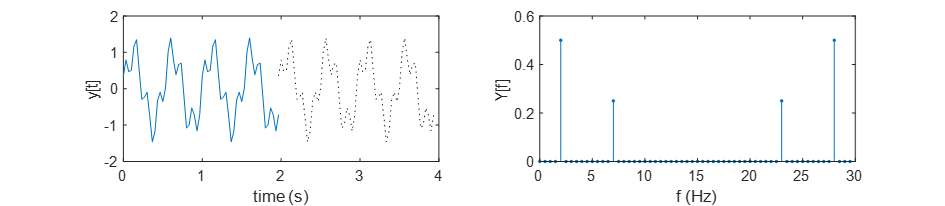

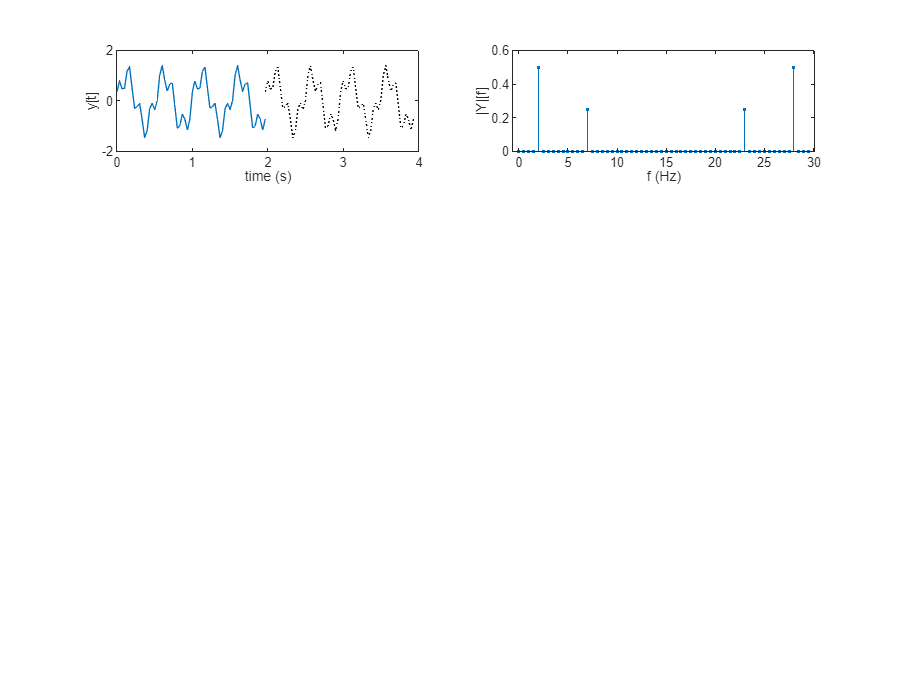

figure(1); clf
set(gcf,'Position',[0 0 800 600])
subplot(4,2,1)
plot(t,y)
hold on
plot(t+t(end),y,':k')
xlabel("time (s)")
ylabel("y[t]")
hold off
subplot(4,2,2)
stem(f,abs(Y),'.')
xlabel("f (Hz)")
ylabel("|Y|[f]")

**Zkraťte signál o 300 ms, což naruší periodicitu. Opět spočtěte jeho spektrum. **

y=y(1:end-round(0.3*fs)); % zkrácení signálu o 300 ms
t=t(1:end-round(0.3*fs)); % zkrácení časové osy o 300 ms
N = fs*(T-0.3);
Y = 1/length(t).*(fft(y));
f = linspace(0,fs - fs/N,N);

**Vykreslete dvě periody signálu a amplitudové spektrum:**

Všimněte si narušení periodicity na rozhraní period způsobující prosakování ve spektru.

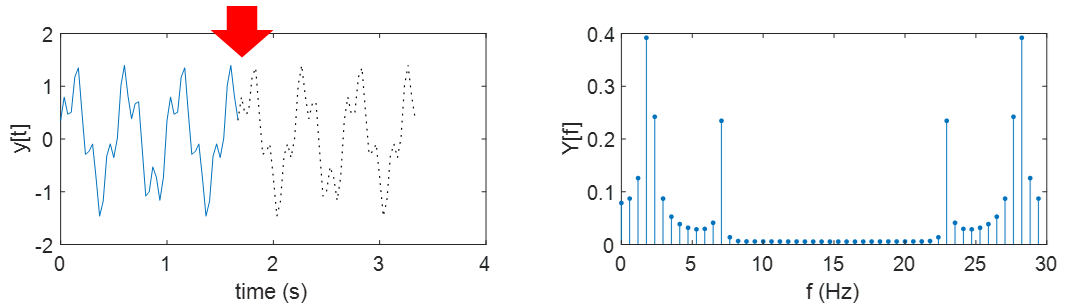

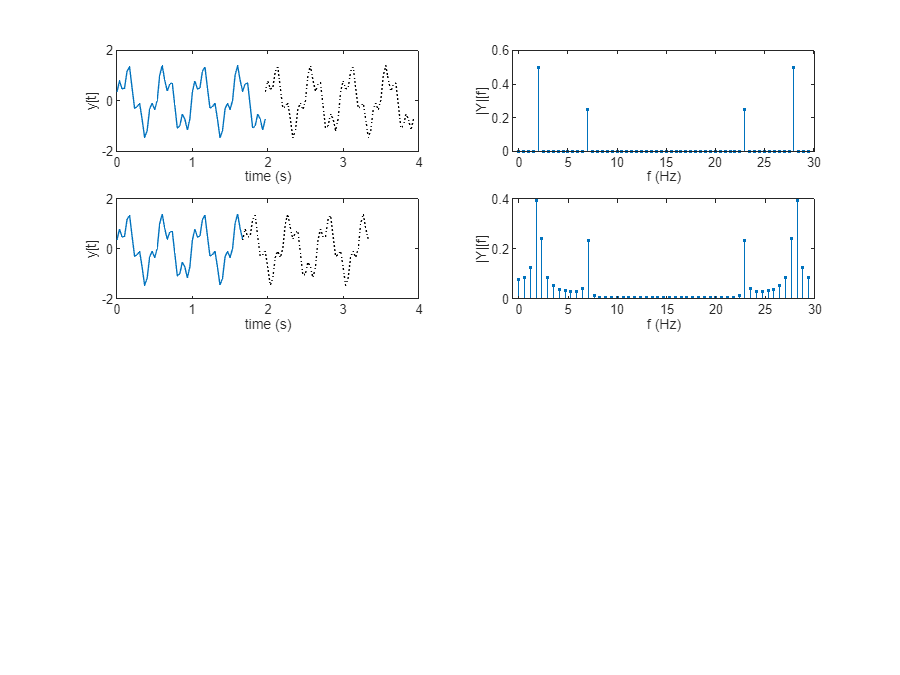

subplot(4,2,3)
plot(t,y)
hold on
plot(t+t(end),y,':k')
xlabel("time (s)")
ylabel("y[t]")
hold off
subplot(4,2,4)
stem(f,abs(Y),'.')
xlabel("f (Hz)")
ylabel("|Y|[f]")

**Odpovězte, co se stane se spektrem signálu po jeho zkrácení o 300 ms?**

Periody signálu na sebe správně nenavazují, proto dojde k prosakovaní.

**Váhujte signál Hammingovým oknem (další typy **`doc window`**)**

win =  hamming(length(y));        % win=...
x = y.*win';        % y=... y(t).*w(t) Pozor na orientaci vektorů!
X = 1/N*fft(x);

**Vykreslete dvě periody signálu a amplitudové spektrum, včetně váhovacího okna:**

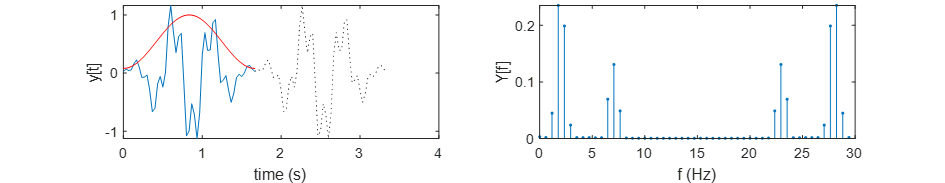

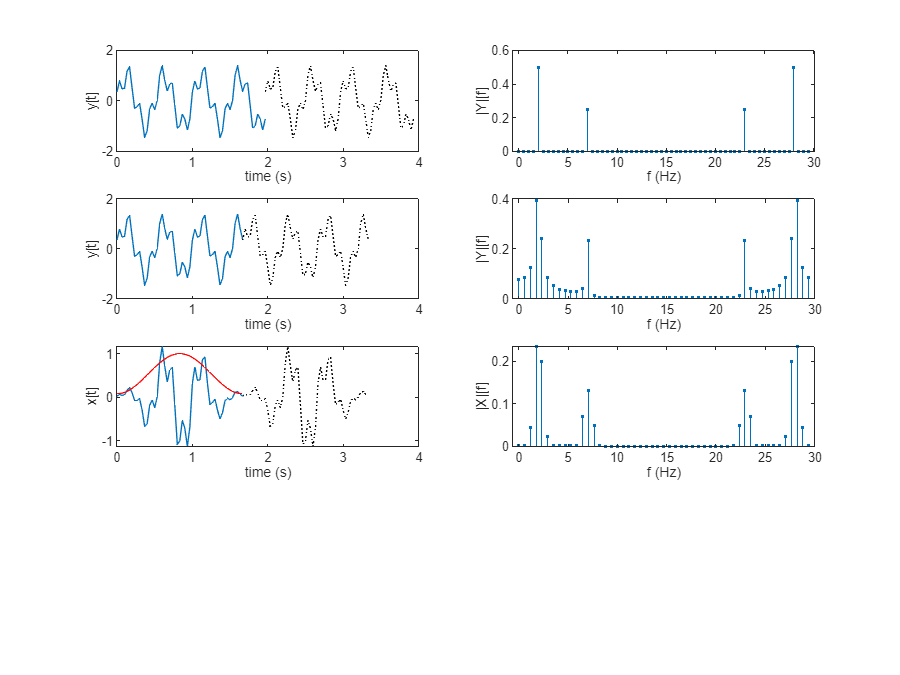

subplot(4,2,5)
plot(t,x)
hold on
plot(t+t(end),x,':k')
xlabel("time (s)")
ylabel("x[t]")
plot(t,win,'r')
hold off
subplot(4,2,6)
stem(f,abs(X),'.')
xlabel("f (Hz)")
ylabel("|X|[f]")

**Odpovězte, co se stane se spektrem signálu po převážení oknem?**

Omezí se efekt prosakování, za cenu rozmazání spektra a snížení energie spektra.

**Doplňte signál nulami a spočtěte jeho spektrum**

Na konec signálu přidejte nulový vektor o délce odpovídající 2 s.

x =[x zeros(1,fs*2)];
N = length(x);
t=linspace(0,(N-1)/fs,N);

X = 1/N.*fft(x);
f = linspace(0,fs -fs/N,N);

 Zobrazte dvě periody signálu a jeho amplitudové spektrum:

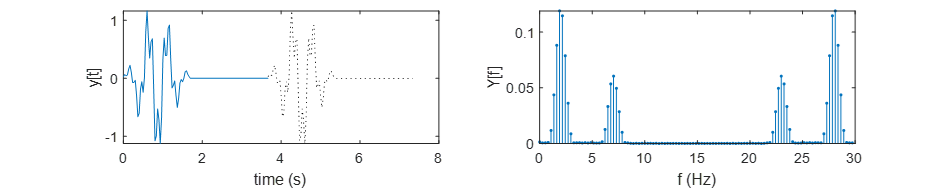

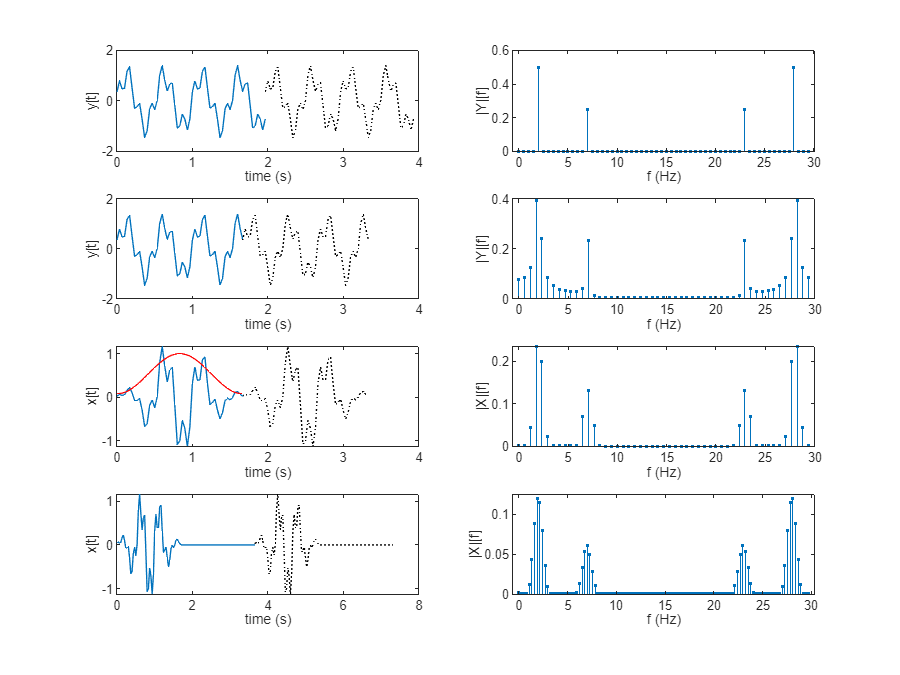

subplot(4,2,7)
plot(t,x)
hold on
plot(t+t(end),x,':k')
xlabel("time (s)")
ylabel("x[t]")

hold off
subplot (4,2,8)
stem(f,abs(X),'.')
xlabel("f (Hz)")
ylabel("|X|[f]")
ylim([0 0.125])

**Odpovězte, co se stane se spektrem signálu po doplnění signálu nulami?**

Spektrum se zahustí.

**Odpovězte, jak se liší amplituda harmonické složky **$f_1$ **oproti zadané a vysvětlete příčinu:**

- **při genezi a ve spektru z celou periodou: **je poloviční, kvůlí zrcadlení spektra.

- **po zkrácení signálu: **se sníží oproti celé periodě kvůli prosáknutí a rozdělení energie i mezi tyto nové frekvence.

- **po váhování oknem: **se opět sníží protože okno utlumí signál (sníží celkovou energii)  na začátku a na konci okna.

- **po doplnění nulami: **se opět sníží amplituda f1, protože se spektrum zahustilo, ale celková energie zůstala stejná (=> nižší aplituda pro konkrétní frekvence).

### 2) Implementace funkce spektrogram

Ze signálu budeme postupně vybírat časové úseky stejné délky tzv. **segmenty **(`i`). Délka segmentu odpovídá velikosti **okna **ve vzorcích (`ww`), které je postupně posouváno od začátku po konec signálu. Krok posunu je závislý na překryvu dvou oken (**negativní překryv **`nn`), tj. u 80% negativního překryvu bude krok 20% (`ww-nn`).

 Nejprve si vytvoříme vektor indexů `idx` odkazující na začátek každého okna. Poslední okno musí odkazovat na vzorky v rozsahu `idx(end) až idx(end)+ww-1`, kde (`idx(end)+ww-1)`$\le$`N. `  

Vygenerujte si testovací chirp signál, tj. spojitý signál měnící svoji frekvenci v čase.

Doba trvání *T*=6 s, s lineárně rostoucí frekvencí od 20 do 600 Hz. 

Vzorkovací kmitočet použijte 1000 Hz.

Pozor.: Horní kmitočet 600 Hz je zvolen úmyslně nad $\frac{f_s }{2}$ pro demonstraci aliasingu při nedodržení vzorkovacího teorému $f_{\max } <\frac{f_s }{2}$.

 Detail 0 až 0.7s z celkových 6 s:

 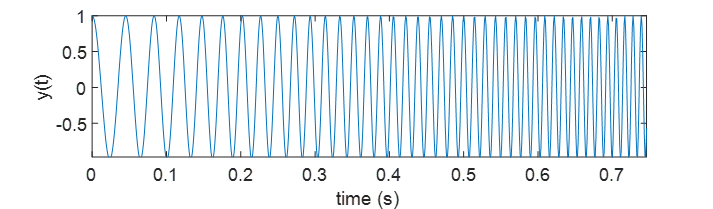

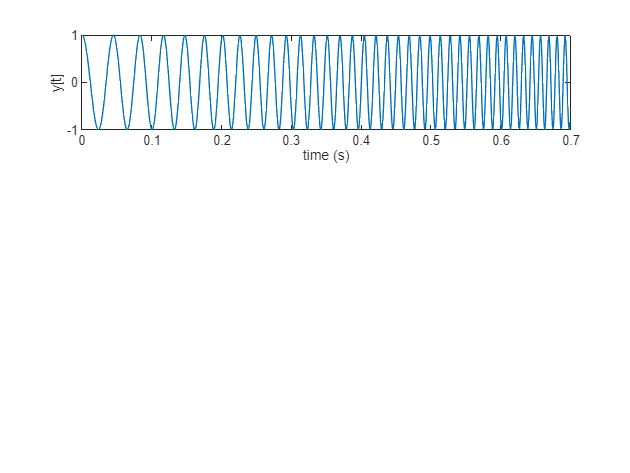

clear all; close all;
T = 6;
fs = 1000;
t = linspace(0,T-1/fs,T*fs);        % vytvořte si časovou osu t=...
y=chirp(t,20,6,600);
sound(y,fs); % přeghrajte si chirp signál
subplot(3,1,1)
idx = (t>=0) & (t<=0.7);
plot(t(idx),y(idx))
ylabel("y[t]")
xlabel("time (s)")

**Časová segmentace:**

ww=0.5*fs; % velikost okna 0.5s ve vzorcích
nn=round(0.75*ww); % 75% negativní překryv v celých vzorcích
n=nextpow2(ww); % nejbližší vyšší mocnina 2^n (tj. n=9 -> 2^9=512, pro ww=500)
zz=2^n-ww;      % počet nul k prodloužení signálu pro optimální výpočet FFT. (2^n-N) 
N = ww+zz;

**Pochopte a zapamatujte si konstrukci indexů začátků oken segmentace s překryvem:**

idx=1:ww-nn:length(y)-ww+1; % ww=velikost okna, nn= negativní překryv (ve vzorcích)

**Algoritmus výpočtu:**

- výběr segmentu y(`idx(i):idx(i)+ww-1)`

- váhování oknem `.*win`

- doplnění nulami `[ ...  zz]`

- výpočet spektra `fft()`

- výpočet výkonového spektra v dB `10*log10()` 

Výstupem spektrogramu je dvourozměrná matice $S\left(f_k ,T_n \right)$. Zamyslete se a určete, jaký bude mít výsledná matice rozměr. Napovím, že počet časových segmentů $T_n$ odpovídá počtu segmentačních oken, tedy i počtu indexů odkazujících na jejich začátek. 

Víte, že počet spektrálních čar při DFT se rovná počtu vzorků signálu $K=N$. Signál zde reprezentuje vždy jeden segment délky okna, který je ale doplněn nulami (N`=ww+zz`)!

Dejte si při výpočtu výkonového spektra (spektrální výkonové hustoty PSD) pozor, kde normujete počtem vzorků $S\left(f_k \right)=\frac{1}{N}{\left|X\left(f_k \right)\right|}^2$ vs. nesprávně $S\left(f_k \right)={\left|\frac{1}{N}X\left(f_k \right)\right|}^2$.

 S = zeros(N,length(idx));       % S=zeros(... , ...) rezervace matice S v paměti o rozměru f_k X T_n
 win = hamming(ww);       % win=... váhovací okno délky ww 

for i=1:length(idx)

yseg = y(idx(i):(idx(i)+ww -1));            % yseg= výběr segmentu ze signálu y()
ywin = yseg.*win';            % váhování segmentu oknem (pozor na orientaci vektorů a vstupem funkce pro vytvoření okna je jedno číslo - zvažte, jestli je nutno použít funkci lenght)
yzeros = [ywin zeros(1,zz)];            % doplnění segmentu nulami

PSD = 1/length(yzeros).*abs(fft(yzeros)).^2;            % výpočet výkonového spektra (PSD) (pozor na normalizaci délkou signálu bez umocnění)

S(:,i) = PSD;            % S(:,i)=...  uložení PSD do matice S
end

Ke spektrogramu `S` ještě vygenerujte příslušnou frekvenční osu `F`. Nezapomeňte, že počet spektrálních čar musí odpovídat velikosti segmentu, tj. `ww+zz`. 

F = linspace(0,fs-fs/N,N);        % F=... frekvenční osa spektrogramu
Sdb = 10*log10(S);
% KONTROLA: frekvenční osa F odpovídá délce segmentu (Nseg=ww+zz)
if length(F)~=size(S,1); error('frekvenční osu mám špatně'); end

Vygenerujte také časovou osu segmentů Tn. Můžeme využít indexů segmentace:

V praxi se ale častěji indexuje do středu segmentačního okna, proto:

Tn=(idx+ww/2)/fs; % časová osa spektrogramu

**Zobrazte spektrogram**

Využijte grafu `imagesc()`, který zobrazuje hodnoty matice v barevné škále.

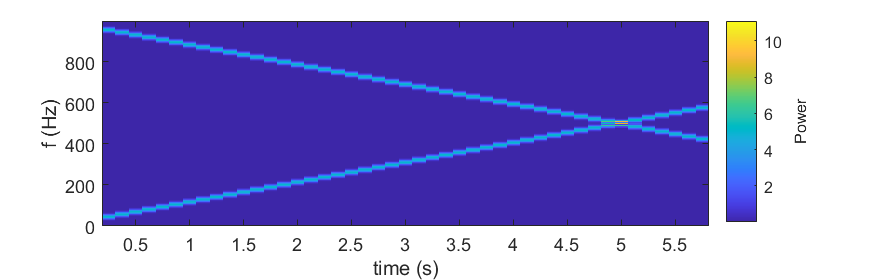

subplot(3,1,2)
imagesc(Tn,F,S)

c=colorbar; % zobrazí barevnou škálu. Handle grafu uloží do struktury "c"
c.Label.String='Power'; % změna popisku colorbaru
xlabel('time (s)'); ylabel('f (Hz)')
axis xy; % osa y zdola nahoru

Zobrazte spektrogram i v dB

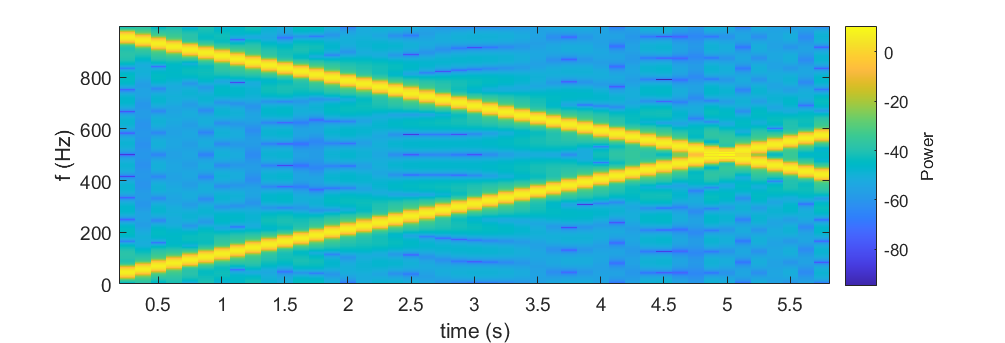

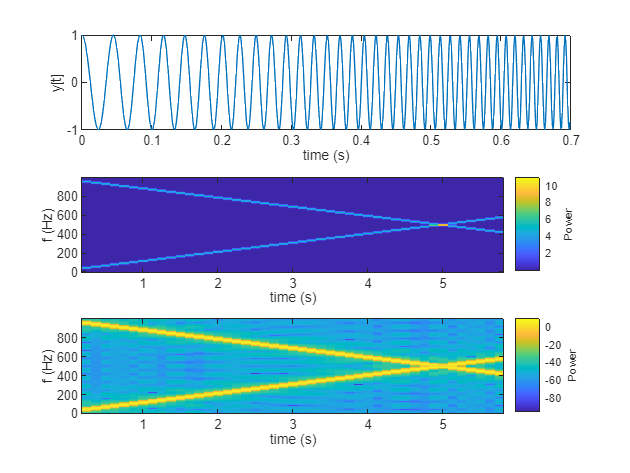

subplot(3,1,3)
imagesc(Tn,F,Sdb)

c=colorbar; % zobrazí barevnou škálu. Handle grafu uloží do struktury "c"
c.Label.String='Power'; % změna popisku colorbaru
xlabel('time (s)'); ylabel('f (Hz)')
axis xy; % osa y zdola nahoru

**Kdy dochází k aliasingu?**

V čase 5.06 s.

Při frekvenci chirp signálu větší než 500 Hz

**Zapouzdřete algoritmus spektrogramu do funkce **`my_spectrogram.m`**:**

**Pozn.:** Dodržujte předepsané pořadí a počet vstupů i výstupů. Můžete do funkce přidat 4. výstup matice spektrogramu přepočtenou na dB škálu $S_{\textrm{dB}}$, bude se v budoucnu hodit.

### 3) Pomocí vlastní implementace zobrazte spektrogramy vybraných signálů

Znovu si vygenerujte chirp signál tentokrát délce 5 s, 20-500 Hz, při $f_s =$1 kHz (již bez aliasingu).

fs=1000;
t=0:1/fs:5-1/fs;        % vytvořte si časovou osu t=...
y=chirp(t,20,5,500);

Do signálu přičtěte 50 Hz harmonickou složku o amplitudě 0.05 simulující síťové rušení.

y = y + 0.05*sin(2*pi*50*t);        % y+0.05*sin(...) 

Spočítejte výkonové spektrum pro dvě různá nastavení segmentace:

- ww=2 s, nn=75 %

- ww=0,2 s, nn=75 % 

**Zobrazte v lineární i dB míře:**

**Následující obrázky jsou pro jiné nastavení než je v zadání, proto vychází trochu jinak.**

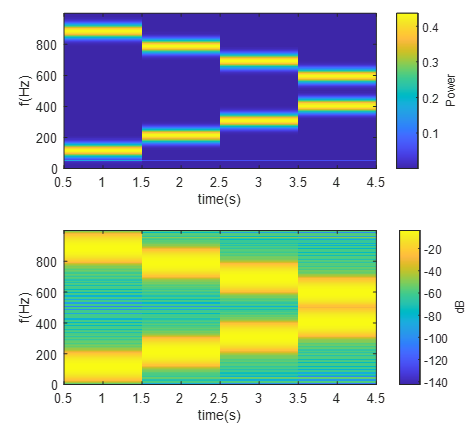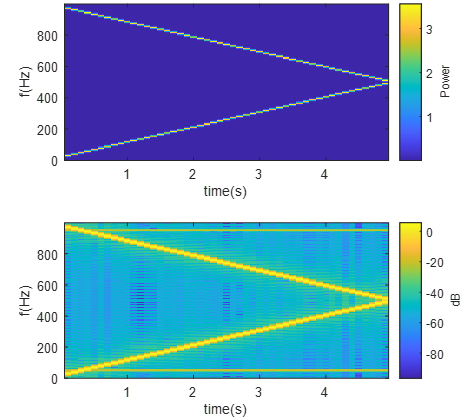

**Doplňte kód:**

figure
set(gcf,'Position',[0 0 800 400])
subplot(2,2,1)
ww = 2*fs;        % ww=... 1) 2s 2) 0.2s 
nn = round(0.75*ww);        % nn=... 75 % okna
n=nextpow2(ww);
zz=2^n-ww; % zz=...
[S1,F,Tn,Sdb1]=my_spectrogram(y,ww,nn,zz,fs);
imagesc(Tn,F,S1);
disp(abs(F(1)-F(2)))

    0.4883



c=colorbar; % zobrazí barevnou škálu. Handle grafu uloží do struktury "c"
c.Label.String='Power'; % změna popisku colorbaru
xlabel('time (s)'); 
ylabel('f (Hz)')
axis xy; % osa y zdola nahoru

subplot(2,2,2)
ww = 0.2*fs;        % ww=... 1) 2s 2) 0.2s 
nn = round(0.75*ww);        % nn=... 75 % okna
n=nextpow2(ww);
zz=2^n-ww; % zz=...
[S2,F,Tn,Sdb2]=my_spectrogram(y,ww,nn,zz,fs);
imagesc(Tn,F,S2);
disp(abs(F(1)-F(2)))

    3.9062



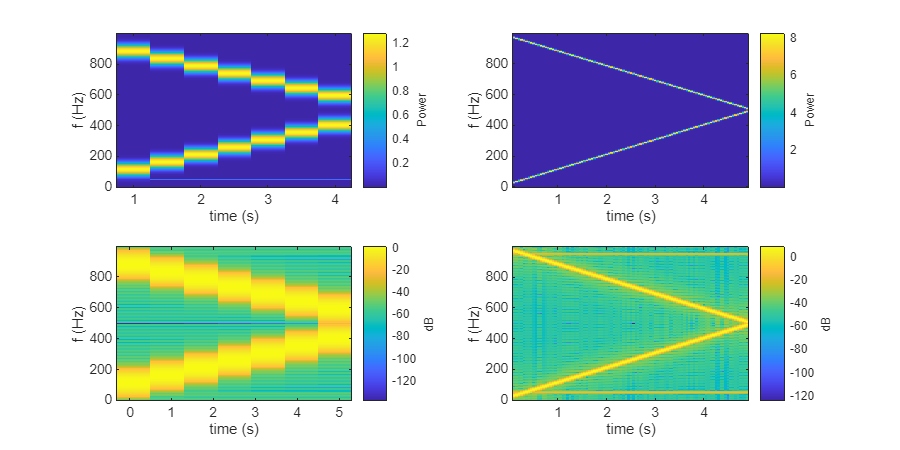

c=colorbar; % zobrazí barevnou škálu. Handle grafu uloží do struktury "c"
c.Label.String='Power'; % změna popisku colorbaru
xlabel('time (s)'); 
ylabel('f (Hz)')
axis xy; % osa y zdola nahoru

subplot(2,2,3)
imagesc(Tn,F,Sdb1);
c=colorbar; % zobrazí barevnou škálu. Handle grafu uloží do struktury "c"
c.Label.String='dB'; % změna popisku colorbaru
xlabel('time (s)'); 
ylabel('f (Hz)');
axis xy; % osa y zdola nahoru

subplot(2,2,4)
imagesc(Tn,F,Sdb2);
c=colorbar; % zobrazí barevnou škálu. Handle grafu uloží do struktury "c"
c.Label.String='dB'; % změna popisku colorbaru
xlabel('time (s)'); 
ylabel('f (Hz)');
axis xy; % osa y zdola nahoru

Prohlédněte si rozdíly mezi spektrogramy a zamyslete se nad velikostí segmentačního okna a jeho vlivu na časové a frekvenční rozlišení, které je patrné zejména na 50 Hz rušení (přibližte si spektrální  čáru 50 Hz).

**Odpovězte na otázky:**

Jaké je frekvenční rozlišení $\Delta f$ pro segmentační okno `ww=2` s? Jak vypadá spektrální čára 50 Hz rušení?

$\Delta f$= 0.4483Hz  

Spektrální čára 50Hz je roztažená zhruba od 49.08Hz-50.53Hz

Jaké je frekvenční rozlišení $\Delta f$ pro segmentační okno `ww=0.2` s? Jak vypadá spektrální čára 50 Hz rušení?

$\Delta f$= 3.9062Hz 

Spektrální čára 50Hz by se v tomto rozlišení měla zobrazit někam na 46-54Hz. Má však nízkou amplitudu a při takto širokém frekvenčním rozlišení se ani viditelně nezobrazí. 

Lze lépe 50 Hz rušení identifikovat v lineární nebo dB škále?

v dB škále

Proč složky chirp signálu vidíme rozmazané při 2 s segmentaci a více ostře při 0,2 s  segmentaci, ačkoli u 50 Hz složky je tomu obráceně? Nápověda: jak je to se stacionaritou? 

Úsek chirp signálu při segmentaci 2 s obsahuje více frekvencí než u segmentace 0.2s. Není stacionární, proto pro delší časové okno působí rozmazaněji. Při krátkém okně máme malé frekvenční rozlišení, proto 50 Hz vypadá rozmazaně.

**Krátký harmonický zázněj v šumu:**

Při analýze neznámého signál je spektrogram analytickým** nástrojem první volby**. Pro identifikaci rychlých změn v charakteru signálu nebo krátkých událostí je potřeba volit dostatečně krátké segmentační okno, tedy preferovat velké časové rozlišení. To je nicméně za cenu malého frekvenčního rozlišení. Naopak, při co nejpřesnějším měření frekvence preferujeme velké frekvenční rozlišení, které vyžaduje velké segmentační okno.

Načtěte si signál v `BeepInNoise.mat`.

clear all 
load('BeepInNoise.mat'); % obsahuje signál "z" a vzorkovací kmitočet "fs"

Zobrazte a poslechněte si signál:

sound(z,fs) % poslechněte si zvuk

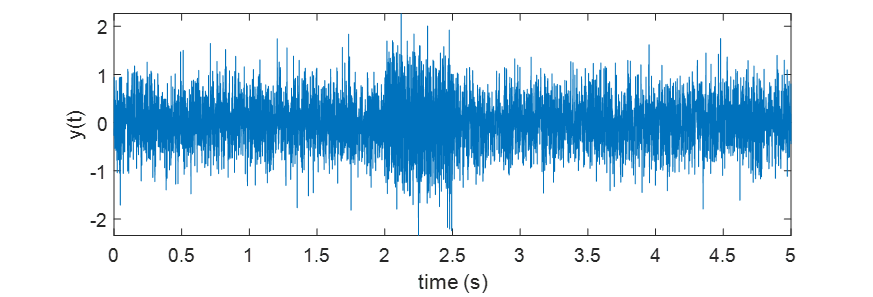

Volte parametry spektrogramu tak, abyste dokázali co nejpřesněji určit, kdy pípnutí začalo, skončilo a jakou frekvenci mělo.  Vyzkoušejte lineární i dB míru.

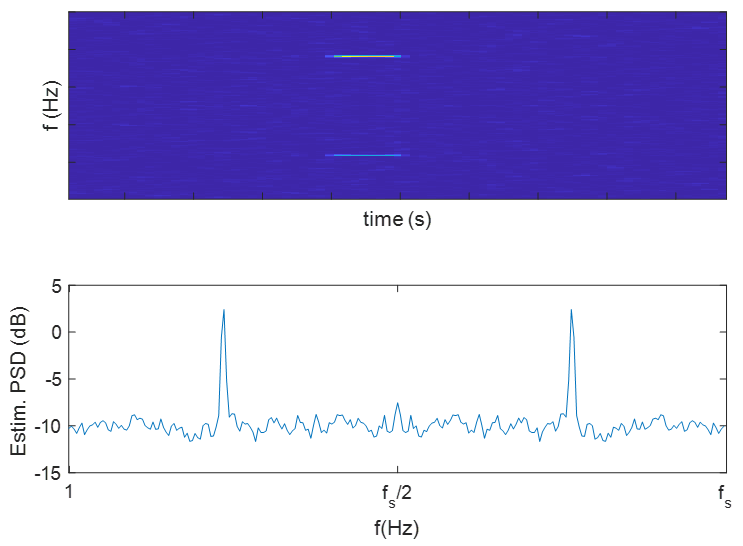Pozn.: pouze příklad, jaké spektrum očekávat

Nápověda: většinou se postupuje od vysokého časového rozlišení (malé okno), abychom zachytily hledaný jev a zároveň se nám neskryl v úzkých spektrálních čarách. Z poslechu odhadněte, jak dlouho pípnutí trvá a zvolte délku segmentačního okna několikanásobně menší. Např.: pokud jev trvá sekundu, zvolte např. 200 ms okno. Pokud jev ve spektrogramu naleznete, snižujte dále délku segmentačního okna k dosažení co největšího časového rozlišení s ještě dostatečným frekvenčním rozlišením.

Pokud již víte, kdy jev nastal, můžete segmentační okno naopak výrazně zvětšit a v čase pípnutí přesně odečíst jeho frekvenci.

**Zobrazte spektrogram i odhad PSD Welchovou metodou:**


$$\begin{array}{l}
\bar{Y_{\textrm{PSD}} } \left(f_k \right)=\frac{1}{W}\sum_w |Y\left(f_k ,t_w \right)|^2 ;\;\;\;W\;\ldotp \ldotp \ldotp \textrm{počet}\;\textrm{segmentačních}\;\textrm{oken}\\
\bar{Y_{\textrm{PSD}} } \left(f_k \right)\;\left\lbrack \textrm{dB}\right\rbrack =10\;\log_{10} \left(\bar{Y_{\textrm{PSD}} } \left(f_k \right)\;\right)
\end{array}$$


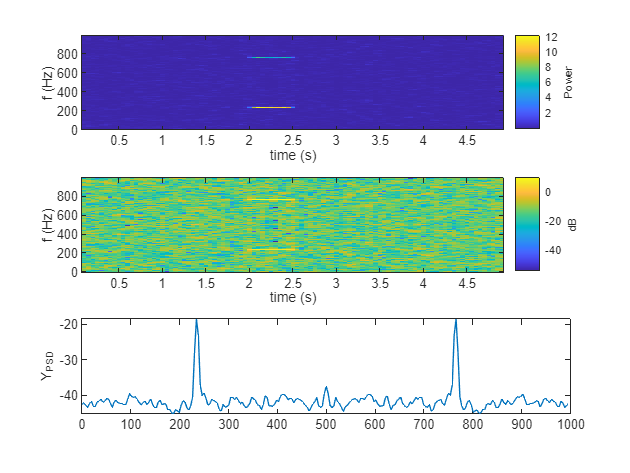

ww = 0.2*fs;
nn = round(0.75*ww);
n = nextpow2(ww);
zz = 2^n -ww;
N = ww + zz;
[S,F,Tn,Sdb]=my_spectrogram(z,ww,nn,zz,fs);

figure
subplot(3,1,1)
imagesc(Tn,F,S)
c=colorbar; 
c.Label.String='Power'; 
xlabel('time (s)'); 
ylabel('f (Hz)')
axis xy; 

subplot(3,1,2)
imagesc(Tn,F,Sdb)
c=colorbar; % zobrazí barevnou škálu. Handle grafu uloží do struktury "c"
c.Label.String='dB'; % změna popisku colorbaru
xlabel('time (s)'); 
ylabel('f (Hz)')
axis xy

avrSw= mean(S,2);
Ypsd = 1/(length(Tn)).*(abs(avrSw).^2);
Ypsd = 10*log10(Ypsd);
subplot(3,1,3)
plot(F,Ypsd);
ylabel("Y_{PSD}")

**Analyzujte signál a hodnoty zapište:**

Pípnutí začalo v čase: 1.988 s (odečteno z dB škály pro ww = 0.05 s)

Pípnutí odeznělo v čase: 2.504 s (odečteno z dB škály pro ww = 0.05 s)

Frekvence pípnutí je: 235.4 Hz (odečteno z lineární škály pro ww = 1 s)

## **BONUS (1b)**

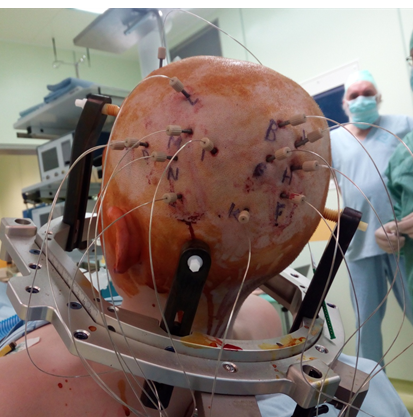 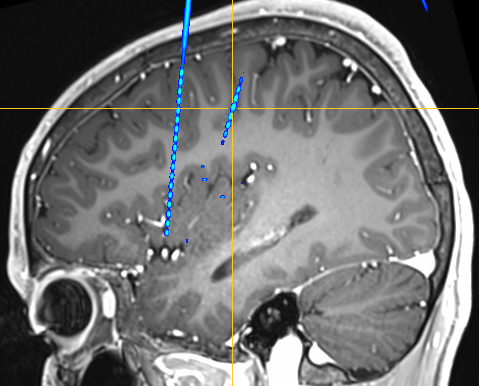

Při chirurgické léčbě farmakorezistentní epilepsie jsou pacientovy chirurgicky zaváděny intracerebrální Stereo-EEG elektrody k identifikaci epileptiformní tkáně. Elektrody procházejí i zdravou tkání a zaznamenávají tak i běžnou mozkovou aktivitu. Pro hodnocení spánku využijete měřený signál pouze mezi dvojicí kontaktů (bipolární pár) z motorické oblasti mozku (viz kříž v MRI výše), která je zodpovědná za plánování pohybu a řízení svalů.

**Motorická oblast je charakteristická přítomností elektrofyziologické aktivity nazývané mu-rytmus (mu-aktivita)**. Spektrálně mu-rytmus nejčastěji** zasahuje do pásma 10-15 Hz**, současně však můžeme pozorovat synchronizované/desynchronizované složky motorické aktivity i v **alfa pásmu (8-13 Hz)** a **beta pásmu (14-30 Hz)**. Mu-rytmus má inhibiční charakter a vyskytuje se ve svalovém klidu. Při volním zapojení svalů dochází k nejprve k desynchronizaci (ERD - evoked related desynchronization) a následnému potlačení mu-aktivity. 

Mu-aktivita přítomná v bdění **vymizí během hlubokého spánku** (NREM - non rapid eye movement) a je nahrazena **delta vlnami (1-4 Hz) s vyšší amplitudou**.

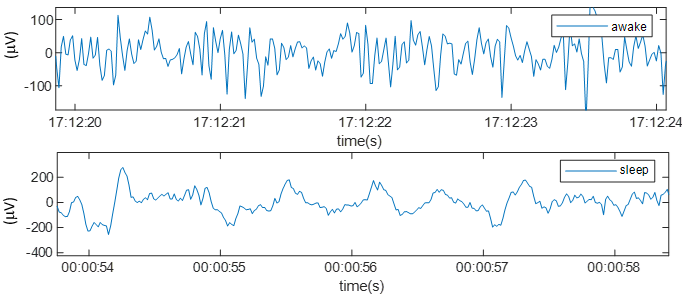 

Načtěte signál a vhodně zobrazte spektrogram signálu. Parametry spektrogramu a jeho vykreslení volte tak, aby bylo jasně patrné střídání bdění a spánku.

**Data:**

- **24 hodin záznamu,**

- **Vzorkovací kmitočet** ${\mathit{\mathbf{f}}}_{\mathit{\mathbf{s}}}$** = 128 Hz** (decimováno z 2048 Hz),

- **Soubor:**` 2297794_D15-16_continuous_fs128Hz_v2025.mat,`

- `d` ... signál iEEG ($\mu$V),

- `fs` ... vzorkovací kmitočet (Hz),

- `tabs` ... časová osa v datenum formátu (kóduje datum a čas záznamu).

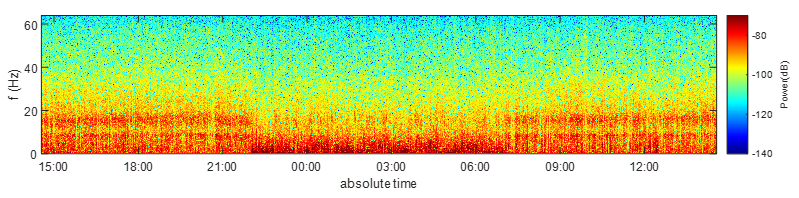

**Tip: **

- Zamyslete se nad vhodnou volbou velikosti segmentačního okna a překryvu (od negativního překryvu přes mezeru mezi segmenty). Nezapomínejme, že střídání fází spánku/bdění je na škálách jednotek až desítek minut.

- Pro zobrazení můžete využívat absolutního času v datenum formátu.

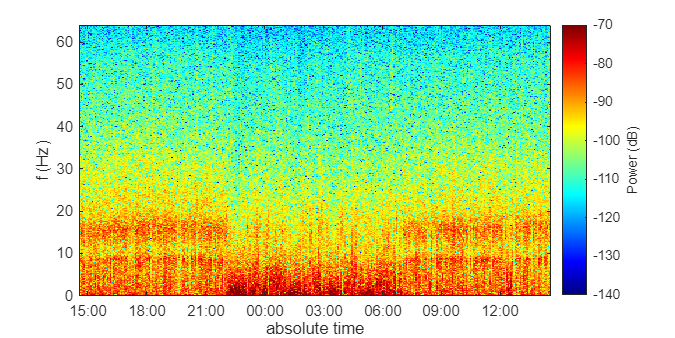

clear all; close all;
load("2297794_D15-16_continuous_fs128Hz_v2025.mat")
d = (d.*1e-6)'; %p5evod uV na V
% vytvořte vektor indexů segmentačních oken
ww=10*fs; % velikost okna (vzorky)
nn=round(0.1*ww); % překryv (vzorky)
n = nextpow2(ww);
zz = 2^n - ww;
N = ww + zz;
index=1:ww-nn:length(d)-ww+1;

Tabs=tabs(round(index+ww/2)); % absolutní čas uprostřed okna
[S,F,Tn,Sdb]=my_spectrogram(d,ww,nn,zz,fs);
idx = F<=fs/2;
figure
set(gcf, 'Position',[0 0 600 300])
imagesc(Tabs,F(idx),Sdb(idx,:))
datetick('x','HH:MM') % zobrazení x osy v datenum formátu hodiny:minuty
axis tight
axis xy
ylim([0 fs/2])
colormap jet % nastavení palety barev - podívejte se do dokumentace, můžete si ji sami zvolit
% pro nastavení colorbar
c = colorbar; % Zobrazení colorbar a nahrání jeho odkazu do proměnné c
c.Label.String='Power (dB)'; % popisek colorbaru
clim([-140 -70]) % nastavení limit colorbaru
xlabel("absolute time");
ylabel("f (Hz)");

Vyberte libovolný úsek spánku a bdění a **odhadněte výkonovou spektrální hustotu **pomocí Welchovy metody.

Tip: vyzkoušejte funkci `ginput`

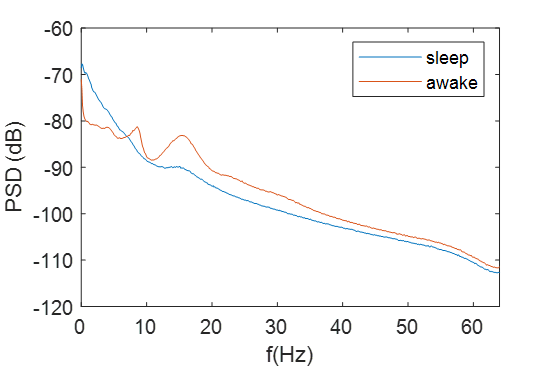

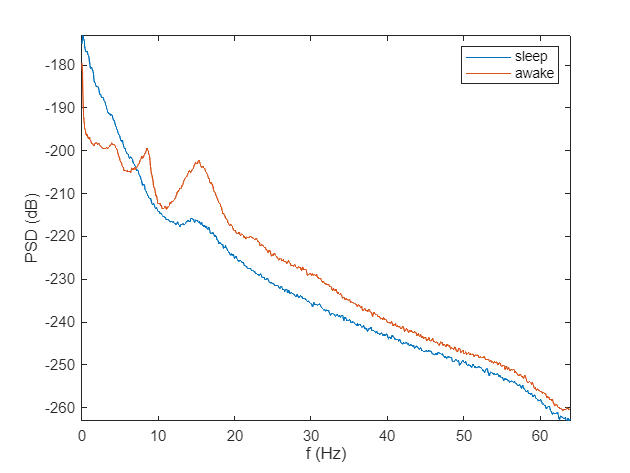

idxAwake = ((Tn >=0) & (Tn <= 10800)); % 3 hodinový segment
idxSleep = (Tn >=32400) & (Tn<= 43200); % 3 hodinový segment
Sawake = S(:,idxAwake);
Ssleep = S(:,idxSleep);

avrSawake = mean(Sawake,2);

PSDawake =  1/height(Sawake).*(abs(avrSawake).^2);
PSDawake = 10*log10(PSDawake);

avrSsleep = mean(Ssleep,2);
PSDsleep =  1/height(Ssleep).*(abs(avrSsleep).^2);
PSDsleep = 10*log10(PSDsleep);

idx = F<=fs/2;
figure
plot(F(idx), PSDsleep(idx));
hold on
plot(F(idx),PSDawake(idx))
axis tight
ylabel("PSD (dB)");
xlabel("f (Hz)")
legend("sleep","awake")
hold off

**Odpovězte:**

Jaké jsou pro daného pacianta dominantní frekvence mu-rytmu:

alfa pásmo je 8.5  Hz

beta pásmo je 15.5 Hz 